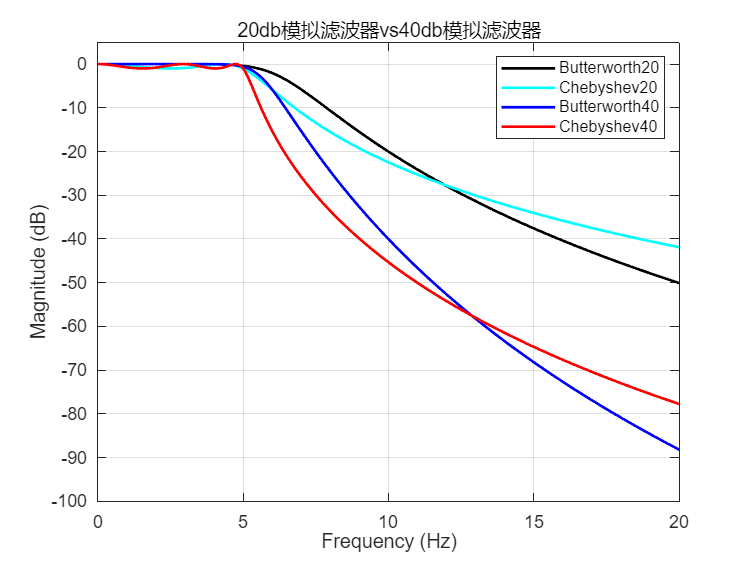

clc;
clear;
close all;

% 定义参数
fs = 100; % 采样频率 (假设采样频率为100 Hz)
fp = 5; % 通带频率
fs_stop = 10; % 阻带频率
wp = 2 * pi * fp; % 模拟通带频率
ws = 2 * pi * fs_stop; % 模拟阻带频率

% 参数1
rp1 = 1; % 通带波动(dB)
rs1 = 20; % 阻带衰减(dB)

% 参数2
rp2 = 1; % 通带波动(dB)
rs2 = 40; % 阻带衰减(dB)

% 巴特沃斯滤波器设计

[n_butt1, wc_butt1] = buttord(wp, ws, rp1, rs1, 's');
[b_butt1, a_butt1] = butter(n_butt1, wc_butt1, 'low', 's');
[n_butt2, wc_butt2] = buttord(wp, ws, rp2, rs2, 's');
[b_butt2, a_butt2] = butter(n_butt2, wc_butt2, 'low', 's');

% 切比雪夫滤波器设计

[n_cheby1, wc_cheby1] = cheb1ord(wp, ws, rp1, rs1, 's');
[b_cheby1, a_cheby1] = cheby1(n_cheby1, rp1, wc_cheby1, 'low', 's');
[n_cheby2, wc_cheby2] = cheb1ord(wp, ws, rp2, rs2, 's');
[b_cheby2, a_cheby2] = cheby1(n_cheby2, rp2, wc_cheby2, 'low', 's');

% 频率响应分析
freq = linspace(0, fs/2, 1000);
w = 2 * pi * freq;

% 巴特沃斯滤波器频率响应
H_butt1 = freqs(b_butt1, a_butt1, w);
H_butt2 = freqs(b_butt2, a_butt2, w);

% 切比雪夫滤波器频率响应
H_cheby1 = freqs(b_cheby1, a_cheby1, w);
H_cheby2 = freqs(b_cheby2, a_cheby2, w);

%一张图中对比两滤波器

figure;
subplot(1, 1, 1);
plot(freq, 20*log10(abs(H_butt1)), 'k', 'LineWidth', 1.5); hold on;
plot(freq, 20*log10(abs(H_cheby1)), 'c', 'LineWidth', 1.5);hold on;
plot(freq, 20*log10(abs(H_butt2)), 'b', 'LineWidth', 1.5); hold on;
plot(freq, 20*log10(abs(H_cheby2)), 'r', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('20db模拟滤波器vs40db模拟滤波器');
legend('Butterworth20', 'Chebyshev20','Butterworth40', 'Chebyshev40');
xlim([0 20]); 
ylim([-100,5]);


% subplot(2, 1, 2);
% plot(freq, 20*log10(abs(H_butt2)), 'b', 'LineWidth', 1.5); hold on;
% plot(freq, 20*log10(abs(H_cheby2)), 'r', 'LineWidth', 1.5);
% grid on;
% xlabel('Frequency (Hz)');
% ylabel('Magnitude (dB)');
% title('40db模拟滤波器: 巴特沃斯 vs 切比雪夫');
% legend('Butterworth', 'Chebyshev');
% xlim([0 20]); 
% ylim([-100,5]);

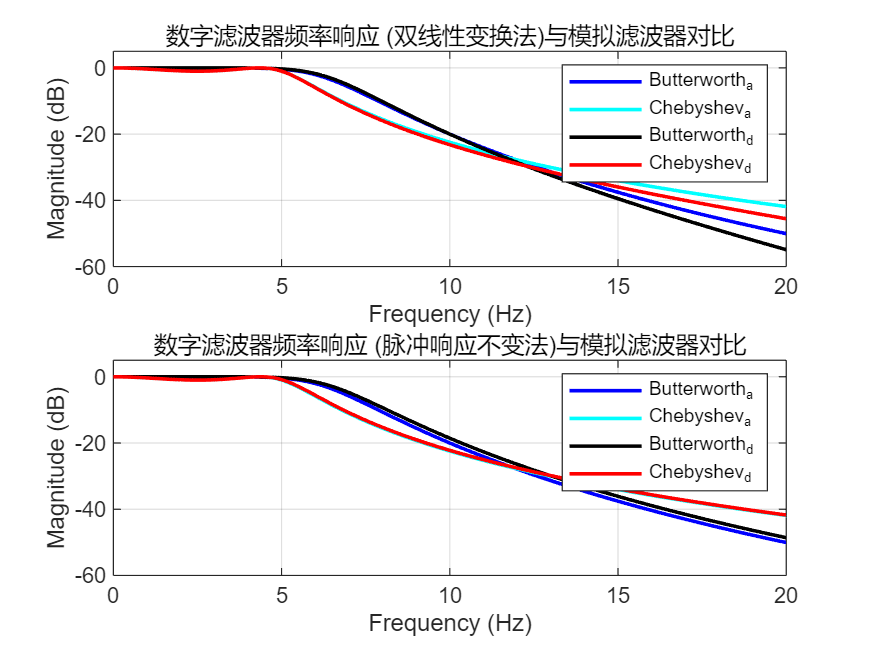


% 定义参数
fs = 100; % 采样频率 (假设采样频率为100 Hz)
fp = 5; % 通带频率 (Hz)
fs_stop = 10; % 阻带频率 (Hz)
rp = 1; % 通带波动 (dB)
rs = 20; % 阻带衰减 (dB)

% 转换模拟滤波器频率
wp = 2 * pi * fp; % 模拟通带频率 (rad/s)
ws = 2 * pi * fs_stop; % 模拟阻带频率 (rad/s)

% 计算预畸变频率
wp_d = 2 * fs * tan(wp / (2 * fs));  % 预畸变后的通带频率
ws_d = 2 * fs * tan(ws / (2 * fs));  % 预畸变后的阻带频率

% 巴特沃斯模拟滤波器设计
[n_butt, wc_butt] = buttord(wp_d, ws_d, rp, rs, 's');
[b_butt, a_butt] = butter(n_butt, wc_butt, 'low', 's');

% 切比雪夫模拟滤波器设计
[n_cheby, wc_cheby] = cheb1ord(wp_d, ws_d, rp, rs, 's');
[b_cheby, a_cheby] = cheby1(n_cheby, rp, wc_cheby, 'low', 's');

% 使用双线性变换法转换为数字滤波器
[b_butt_bilinear, a_butt_bilinear] = bilinear(b_butt, a_butt, fs);
[b_cheby_bilinear, a_cheby_bilinear] = bilinear(b_cheby, a_cheby, fs);

% 使用脉冲响应不变法转换为数字滤波器
[b_butt_impinvar, a_butt_impinvar] = impinvar(b_butt, a_butt, fs);
[b_cheby_impinvar, a_cheby_impinvar] = impinvar(b_cheby, a_cheby, fs);

% 计算频率响应
[H_butt_bilinear, w_butt_bilinear] = freqz(b_butt_bilinear, a_butt_bilinear, 1024, fs);
[H_cheby_bilinear, w_cheby_bilinear] = freqz(b_cheby_bilinear, a_cheby_bilinear, 1024, fs);

[H_butt_impinvar, w_butt_impinvar] = freqz(b_butt_impinvar, a_butt_impinvar, 1024, fs);
[H_cheby_impinvar, w_cheby_impinvar] = freqz(b_cheby_impinvar, a_cheby_impinvar, 1024, fs);

% 可视化频率响应
figure;

% 双线性变换法
subplot(2, 1, 1);
plot(freq, 20*log10(abs(H_butt1)), 'b', 'LineWidth', 1.5); hold on;
plot(freq, 20*log10(abs(H_cheby1)), 'c', 'LineWidth', 1.5);hold on;
plot(w_butt_bilinear, 20*log10(abs(H_butt_bilinear)), 'k', 'LineWidth', 1.5); hold on;
plot(w_cheby_bilinear, 20*log10(abs(H_cheby_bilinear)), 'r', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
hold on;
title('数字滤波器频率响应 (双线性变换法)与模拟滤波器对比');
hold on;
legend('Butterworth_a', 'Chebyshev_a','Butterworth_d','Chebyshev_d');
xlim([0 20]);
ylim([-60,5]);

% 脉冲响应不变法
subplot(2, 1, 2);
plot(freq, 20*log10(abs(H_butt1)), 'b', 'LineWidth', 1.5); hold on;
plot(freq, 20*log10(abs(H_cheby1)), 'c', 'LineWidth', 1.5);hold on;
plot(w_butt_impinvar, 20*log10(abs(H_butt_impinvar)), 'k', 'LineWidth', 1.5); hold on;
plot(w_cheby_impinvar, 20*log10(abs(H_cheby_impinvar)), 'r', 'LineWidth', 1.5);hold on;
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('数字滤波器频率响应 (脉冲响应不变法)与模拟滤波器对比');
legend('Butterworth_a', 'Chebyshev_a','Butterworth_d','Chebyshev_d');
xlim([0 20]);
ylim([-60,5]);